# TEST FOR Oper CLASS

## Function test

### Construction test

E = Oper

E =   Oper - 属性:

               R: [3×3 double]
               U: NaN
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0
       strict_eq: 0

U·H(k)·U^-1 = H(R·k)
R = 1


E.pretty('Latex',1)

ans = "\begin{aligned} U H(\mathbf{{k}}) U^{{-1}} &= H(R\mathbf{{k}}) \\R &= 1\\\end{aligned}"

I = Oper(-eye(3),kron(eye(2),[1,0;0,-1]))

I =   Oper - 属性:

               R: [3×3 double]
               U: [4×4 double]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0
       strict_eq: 0

U·H(k)·U^-1 = H(R·k)
R = I
U = [1 0 0 0;0 -1 0 0;0 0 1 0;0 0 0 -1]

fprintf(I.pretty)

U·H(k)·U^-1 = H(R·k)
R = I
U = [1 0 0 0;0 -1 0 0;0 0 1 0;0 0 0 -1]


I.pretty('Latex',1)

ans = "\begin{aligned} U H(\mathbf{{k}}) U^{{-1}} &= H(R\mathbf{{k}}) \\R &= I\\U &= \left(\begin{array}{cccc} 1&0&0&0\\0&-1&0&0\\0&0&1&0\\0&0&0&-1\\\end{array}\right)\end{aligned}"

theta = pi/3;

C3z =Oper(Oper.nTheta2Rotation(theta),expm(kron([1,0;0,-1],1i*[pi/3,0;0,pi])))

C3z =   Oper - 属性:

               R: [3×3 double]
               U: [4×4 double]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0
       strict_eq: 0

U·H(k)·U^-1 = H(R·k)
R = R(pi/3,[0 0 1])
U = [0.5+0.866i 0 0 0;0 -1 0 0;0 0 0.5-0.866i 0;0 0 0 -1]

fprintf(C3z.pretty())

U·H(k)·U^-1 = H(R·k)
R = R(pi/3,[0 0 1])
U = [0.5+0.866i 0 0 0;0 -1 0 0;0 0 0.5-0.866i 0;0 0 0 -1]


C3z.pretty('Latex',1)

ans = "\begin{aligned} U H(\mathbf{{k}}) U^{{-1}} &= H(R\mathbf{{k}}) \\R &= R\left(\frac{\pi }{3},[0 0 1]\right)\\U &= \left(\begin{array}{cccc} e^{i \frac{\pi }{3}}&0&0&0\\0&-1&0&0\\0&0&e^{i -\frac{\pi }{3}}&0\\0&0&0&-1\\\end{array}\right)\end{aligned}"

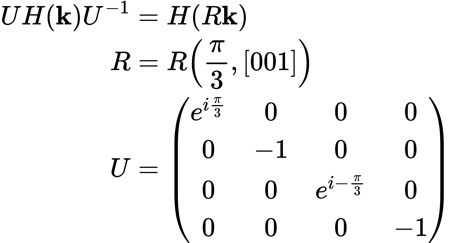

### Construction test2

tr = Oper.time_reversal();
tr = Oper.time_reversal(3,nan,3/2);
P = Oper.particle_hole(3,nan);
Inv = Oper.inversion(3,nan);
Mirror = Oper.mirror([1,0,0]);

A(1) = tr;
A(2) = P;
A(3) = Inv;

B(1) = tr;
B(2) = P;
B(3) = Inv;
B(4) = Mirror;

Square_group = Oper.square(false,false);
cubic_group = Oper.cubic(false,false);
hexagonal_2D_group = Oper.hexagonal_2D(false,false);
hexagonal_group = Oper.hexagonal(false,false);

### Static test

#### name_angle

E = Oper.name_angle(0)

E = "0"

E = Oper.name_angle(0,1)

E = '0'

E = Oper.name_angle(2*pi)

E = "2*pi"

E = Oper.name_angle(3/2*pi,1)

E = '\frac{3\,\pi }{2}'

E = Oper.name_angle(4.7124,1)

E = '\frac{3\,\pi }{2}'

#### Rotation2nTheta

try
    Oper.Rotation2nTheta(1)
catch
    fprintf('use 3*3 R\n')
end

use 3*3 R


Oper.Rotation2nTheta(-eye(3))

det = -1


ans =      1     0     0


theta = pi/2;
[n,theta]= Oper.Rotation2nTheta([cos(theta),sin(theta),0;-sin(theta), cos(theta),0;0 0 1])

n =      0     0     1


theta = 1.5708

### Source_test

#### S_mat = spin_matrices(s, include_0)

Oper.spin_matrices(3/2)

ans = ans(:,:,1) =

   0.0000 + 0.0000i   0.8660 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.8660 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.8660 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.8660 + 0.0000i   0.0000 + 0.0000i


ans(:,:,2) =

   0.0000 + 0.0000i   0.0000 - 0.8660i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.8660i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 - 0.8660i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.8660i   0.0000 + 0.0000i


ans(:,:,3) =

   1.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.5000 + 0.0000i


#### L_mat = L_matrices(d, l)

Oper.L_matrices()

ans = ans(:,:,1) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i


ans(:,:,2) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,3) =

   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


#### Spin_rotation

U = Oper.spin_rotation(pi*[0, 1, 0],3/2)

U =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
